cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

load("../../results/trmse_raw.mat")

seq_starts = find(y_within.w_trial==1)+1

seq_starts =      2
    11
    20
    29
    38
    47


seq_stops = find(y_within.w_trial==9)+1;
num_subjs = height(y_between);
num_seqs =numel(seq_starts);

diff_arr = [];
for j=1:num_seqs
seq = y_between{:, seq_starts(j):seq_stops(j)};
diff_arr = [diff_arr, diff(seq, 1,2)];
end

diff_between = array2table(diff_arr);
diff_between = [y_between(:,1), diff_between]

diff_between = 15×49 table
    b_condition    diff_arr1     diff_arr2     diff_arr3     diff_arr4     diff_arr5     diff_arr6     diff_arr7     diff_arr8     diff_arr9    diff_arr10    diff_arr11    diff_arr12    diff_arr13    diff_arr14     diff_arr15    diff_arr16     diff_arr17     diff_arr18    diff_arr19    diff_arr20    diff_arr21    diff_arr22     diff_arr23    diff_arr24    diff_arr25    diff_arr26    diff_arr27    diff_arr28    diff_arr29     diff_arr30    

diff_within = y_within(any(y_within.w_trial==(1:8),2),["w_task", "w_gesture", "w_trial"])

diff_within = 48×3 table
          w_task              w_gesture        w_trial
    __________________    _________________    _______

    "Machine Learning"    "Co-Activation"         1   
    "Machine Learning"    "Co-Activation"         2   
    "Machine Learning"    "Co-Activation"         3   
    "Machine Learning"    "Co-Activation"         4   
    "Machine Learning"    "Co-Activation"         5   
    "Machine Learning"    "Co-Activation"         6   
    "Machine Learning"    "Co-Activation"         7   
    "Machine Learning"    "Co-Activation"         8   
    "Machine Learning"    "Differentiation"       1   
    "Machine Learning"    "Differentiation"       2   
    "Machine Learning"    "Differentiation"       3   
    "Machine Learning"    "Differentiation"       4   
    "Machine Learning"    "Differentiation"       5   
    "Machine Learning"    "Differentiation"    

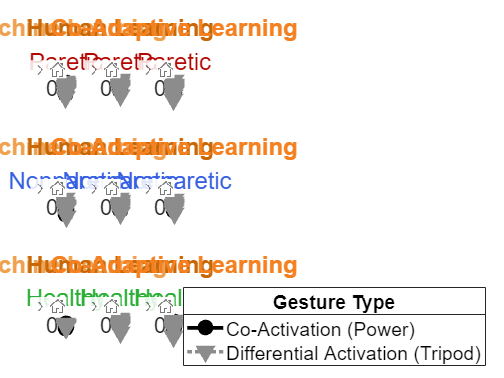

tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
% tlo.Units = 'inches';
% tlo.OuterPosition = [0 0 17 10.5];
ax_handle_list = [];
for cond = ["par", "xpar", "hlt"]
    y_cond = diff_between(diff_between.b_condition==cond,2:end);
    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]
        y_coact = y_cond(:, and(diff_within.w_task == task, diff_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(diff_within.w_task == task, diff_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        plot(y_coact{:,:}', '-ok', 'MarkerFaceColor','k', 'LineWidth',3,'MarkerSize',10 )
        plot(y_diffact{:,:}', ':v', 'MarkerFaceColor',"#8c8c8c", 'LineWidth',3,'MarkerSize',10, 'Color',"#8c8c8c")
        hold off
        title(task)
        switch task
            case "Machine Learning"
                title(task, 'Color', "#f0a150")
            case "Human Learning"
                title(task, 'Color', "#c76706")
            case "Co-Adaptive Learning"
                title(task, 'Color', "#f48020")
        end
        switch cond
            case "par"
                subtitle("Paretic", 'Color', "#b30600")
            case "xpar"
                subtitle("Nonparetic", 'Color', "#3760e3")
            case "hlt"
                subtitle("Healthy", 'Color', "#29af34")
        end
        xticks(1:9)
        % yticks(0:0.2:0.8)
    end
end
legend_handle = legend(["Co-Activation (Power)",repmat("", 1,4), "Differential Activation (Tripod)"], "Location","eastoutside");
title(legend_handle, "Gesture Type")
linkaxes(ax_handle_list, 'xy')
ylim([min(diff_arr,[], 'all'), max(diff_arr,[], 'all')])
xlim([0 10])
% title(tlo, sprintf("%s Vs. Trial Count", upper(metric_type)))
set(ax_handle_list, 'FontSize', 18)

### Export to R

r_dataframe = [];
for i=1:height(diff_between)
    if or(diff_between{i,1} == "par", diff_between{i,1} == "xpar")
        p_id = i+mod(i,2);
    else
        p_id = i;
    end
    p_tbl = array2table([p_between{i,2:end}', repmat(sprintf("p%02d",p_id), height(p_within),1), repmat(p_between{i,1}, height(p_within),1), p_within{:,:}], ...
        "VariableNames", ["rmse", "p_id", "p_cond", "task_type", "gesture_type", "trial_num"]);
    r_dataframe = [r_dataframe; p_tbl];
end

r_dataframe = convertvars(r_dataframe, ["rmse"], 'double');
r_dataframe = convertvars(r_dataframe, ["trial_num"], 'double');
r_dataframe = convertvars(r_dataframe, ["gesture_type", "task_type", "p_cond", "p_id"], 'categorical');
r_dataframe = r_dataframe(:,{'rmse' 'trial_num' 'gesture_type' 'task_type' 'p_cond', 'p_id'})

writetable(r_dataframe, '../../temp-data/rdf_rmse_phi_10.csv','WriteMode','overwrite')